data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]



FWT = data.FWT;
A=data.A;
B=data.B;
C=data.C;
D=data.D;
%print(data)
sys1 = ss(A,B,C,D);

% step(-FWT(1,1));
% bode(-FWT(1,1));
% margin(-FWT(1,1)); 
% pzplot(-FWT(1,1));
% stepinfo(-FWT(1,1));


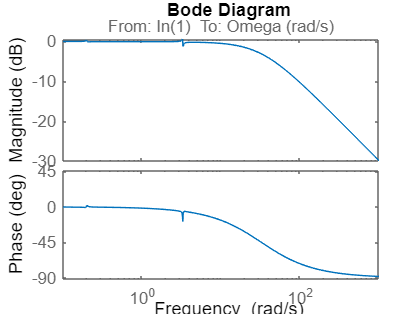

% PID
Plant = -FWT(1,1);
Kp = 400;
Ki = 50.2;
Kd = 0;
Tf = 0.06;
C = pid(Kp,Ki,Kd,Tf);

Polecancel = minreal(Plant*C); % To speed up the calculations
fbsys = feedback(Polecancel,1);
bode(fbsys);

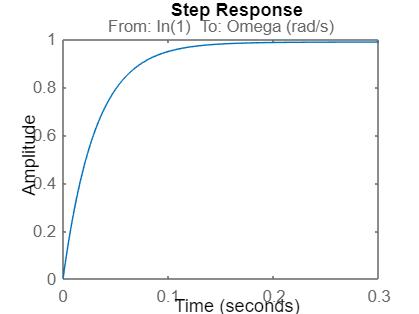

step(fbsys);

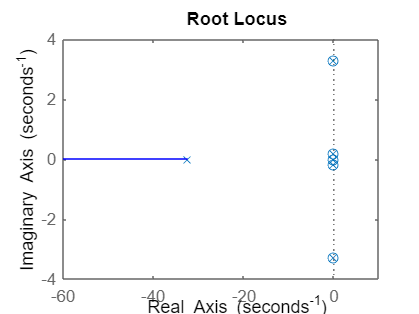

stepinfo(fbsys);
rlocus(fbsys)

% Try to use notch filter
% w1=0.2/(2*pi);
% w2=3.3/(2*pi);
% beta1 = 1;
% beta2 = 10;
% beta3 = 1;
% beta4 = 10;
% 
% num1 = [1,w1*beta1,w1^2];
% den1 = [1, w1*beta2,w1^2];
% num2 = [1,w2*beta3,w2^2];
% den2 = [1, w2*beta3,w2^2];
% 
% C_notch1 = tf(num1,den1);
% C_notch2 = tf(num2,den2);
% 
% % Extra pid
% Kp = 1
% Ki = 1
% Kd = 1
% Tf=0.06
% K = pid(Kp, Ki, Kd, Tf)
% 
% PoleCancel = minreal(Plant*C_notch1*C_notch2)
% sys_cl = feedback(PoleCancel,1);
% 
% bode(sys_cl)
% margin(sys_cl)
% [y,t] = step(sys_cl);
% step(sys_cl);
% stepinfo(sys_cl);
% sserror=abs(1-y(end))